% get eigenface and originalmean from the csv file we save
eigenface=csvread("eigenface.csv");
origmean=csvread("original_mean.csv");
origmean=repmat(origmean,1,100);

% get 1 random photo from each person -> total 100 photos
selectfolderpath="selected_test_images/";

if ~isfolder(selectfolderpath)
    errorMessage=sprintf('Error: The following folder does not exist:\n%s',selectfolderpath);
    uiwait(warndlg(errorMessage));
    return;
end

selectpattern=fullfile(selectfolderpath,'*.bmp');
selectimg=dir(selectpattern);
numofselect=length(selectimg);
if numofselect~=0
    for i=1:numofselect
        fname=fullfile(selectfolderpath,selectimg(i).name);
        delete(fname);
    end
end

testdatapath="/home/dmplus/2019_juniorI/CV/assignment/assignment1/dataset/AR/AR_Test_image";
if ~isfolder(testdatapath)
    errorMessage=sprintf('Error: The following folder does not exist:\n%s',testdatapath);
    uiwait(warndlg(errorMessage));
    return;
end

testpattern=fullfile(testdatapath,'*.bmp');
testimgs=dir(testpattern);
randnumvec=zeros(13,1);

for i=1:100
    randnumvec(i)=randsample(13,1);
end

for i=1:100
    idx=13*(i-1);
    idx=idx+randnumvec(i);
    curfname=fullfile(testdatapath,testimgs(idx).name);
    img=imread(curfname);
    fname=testimgs(idx).name;
    disp(fname);
    imwrite(img,fullfile('selected_test_images/',testimgs(idx).name));
end

m-001-22.bmp
m-002-24.bmp
m-003-18.bmp
m-004-25.bmp
m-005-22.bmp
m-006-16.bmp
m-007-20.bmp
m-008-24.bmp
m-009-16.bmp
m-010-16.bmp
m-011-18.bmp
m-012-19.bmp
m-013-25.bmp
m-014-19.bmp
m-015-17.bmp
m-016-21.bmp
m-017-21.bmp
m-018-16.bmp
m-019-17.bmp
m-020-19.bmp
m-021-15.bmp
m-022-24.bmp
m-023-26.bmp
m-024-20.bmp
m-025-17.bmp
m-026-26.bmp
m-027-20.bmp
m-028-20.bmp
m-029-22.bmp
m-030-18.bmp
m-031-14.bmp
m-032-25.bmp
m-033-15.bmp
m-034-18.bmp
m-035-15.bmp
m-036-15.bmp
m-037-20.bmp
m-038-23.bmp
m-039-25.bmp
m-040-23.bmp
m-041-14.bmp
m-042-20.bmp
m-043-25.bmp
m-044-22.bmp
m-045-24.bmp
m-046-16.bmp
m-047-25.bmp
m-048-20.bmp
m-049-26.bmp
m-050-20.bmp
w-0100-14.bmp
w-051-14.bmp
w-052-20.bmp
w-053-24.bmp
w-054-23.bmp
w-055-22.bmp
w-056-26.bmp
w-057-24.bmp
w-058-19.bmp
w-059-15.bmp
w-060-16.bmp
w-061-24.bmp
w-062-14.bmp
w-063-20.bmp
w-064-22.bmp
w-065-17.bmp
w-066-14.bmp
w-067-16.bmp
w-068-18.bmp
w-069-20.bmp
w-070-26.bmp
w-071-14.bmp
w-072-17.bmp
w-073-21.bmp
w-074-19.bmp
w-075-17.bmp
w-076-22.bm

% preprocess the selected test images
% 1. grayscale 2. matrix -> vector 3. 100 vector concatenate to into 1
% matrix
selectfolderpath="selected_test_images/";

if ~isfolder(selectfolderpath)
    errorMessage=sprintf('Error: The following folder does not exist:\n%s',selectfolderpath);
    uiwait(warndlg(errorMessage));
    return;
end

selectpattern=fullfile(selectfolderpath,'*.bmp');
selectimg=dir(selectpattern);
numofselect=length(selectimg);

imgmat=zeros(19800,100);

for i=1:100
    fname=fullfile(selectfolderpath,selectimg(i).name);
    finfo=imread(fname);
    grayimg=rgb2gray(finfo);
    grayimg=im2double(grayimg);
    vec=grayimg(:);
    imgmat(:,i)=vec;
end

imgmat=imgmat-origmean;

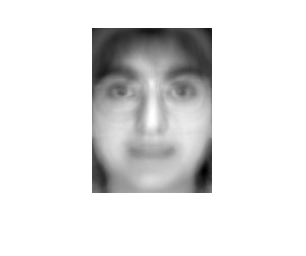

% compress and decompress the image when d=1,5,9
reducedimdir="after_reduce_dimension/";

% d=1
d1path=strcat(reducedimdir,"d1/");
projectimg=imgmat'*eigenface(:,1);
origimg=projectimg*eigenface(:,1)';
origimg=origimg'+origmean;
vec=num2cell(origimg,1);
for i=1:100
    mat=reshape(vec{i},165,120);
    gray=mat2gray(mat);
    %imshow(gray);
    fname=strcat('person',num2str(i));
    imwrite(gray,fullfile(d1path,strcat(fname,'.bmp')));
end

% d=5
d5path=strcat(reducedimdir,"d5/");
projectimg=imgmat'*eigenface(:,1:5);
origimg=projectimg*eigenface(:,1:5)';
origimg=origimg'+origmean;
vec=num2cell(origimg,1);
for i=1:100
    mat=reshape(vec{i},165,120);
    gray=mat2gray(mat);
    %imshow(gray);
    fname=strcat('person',num2str(i));
    imwrite(gray,fullfile(d5path,strcat(fname,'.bmp')));
end

% d=9
d9path=strcat(reducedimdir,"d9/");
projectimg=imgmat'*eigenface(:,1:9);
origimg=projectimg*eigenface(:,1:9)';
origimg=origimg'+origmean;
vec=num2cell(origimg,1);
for i=1:100
    mat=reshape(vec{i},165,120);
    gray=mat2gray(mat);
    imshow(gray);
    fname=strcat('person',num2str(i));
    imwrite(gray,fullfile(d9path,strcat(fname,'.bmp')));
end